# **Matlab案例代码解析**

## 5. 智能优化算法案例

### 5.1 差分进化（DE）

#### 5.1.1 DE求解函数极值

#### 基本流程：

- 初始化：$x_{ji,0}=rand*(x_j^U-x_J^L)+x_J^L$

- 变异：$v_{i,G+1}=x_{r1,G}+F*(x_{r2,G}-x_{r3,G}),F\in{[0,2]}
$

- 交叉：$u_{ji,G+1}=
\left\{
\begin{array}{l}
v_{ji,G+1}&if &rand(j)\leq{CR}&or &j=randi(i)\\
x_{ji,G+1}&if &rand(j)>{CR}&and &j\neq{randi(i)}
\end{array}
\right.$

- 选择：试验值与当前目标值比较，实验值小则更新对应的种群值

- 边界处理：超过边界的可以用范围内随机值代替或者进行边界吸收直接用边界值代替

#### 改进：

自适应差分进化算法：$\lambda = e^{1-\frac{G_m}{G_m+1-G}},F=F_0*2^{\lambda}\\
CR=0.5*(1+rand)$

%%%%%%%%%%%%%  初始化 %%%%%%%%%%%%%
clear; clc;
% 种群数量
NP = 20;   
% 变量维度
D = 2;    
% 最大进化代数
G = 200;    
% 初始变异算子
F0 = 0.5;   
% 交叉算子
CR = 0.1;  
% 上限
Xs = 10; 
% 下限
Xx = -10;
% 阈值
yz = 1e-8;        
%%%%%%%%%%%%%  赋初值 %%%%%%%%%%%%%
Ob = zeros(NP, 1);
Ob1 = zeros(NP, 1);
% 变异种群
v = zeros(D, NP);   
% 选择种群
u = zeros(D, NP);  
% 初始种群
x = rand(D, NP) * (Xs - Xx) + Xx;  
%%%%%%%%%%%%%  计算目标函数 %%%%%%%%%%%%%
for m = 1 : NP
   Ob(m) = ObjFun(x(:, m));
end
%%%%%%%%%%%%%  差分进化循环 %%%%%%%%%%%%%
trace = zeros(G, 1);
trace(1) = min(Ob);
for gen = 1 : G
   %%%%%%%%%%%%%  变异操作 %%%%%%%%%%%%%
   %%%%%%%%%%%%%  自适应变异算子 %%%%%%%%%
   lamda = exp(1 - G / (G + 1 - gen));
   F = F0 * 2^lamda;
   %%%%%%%%%%  r1、r2、r3和m互不相同 %%%%%%%%%%
   for m = 1 : NP
      r1 = randi([1, NP], 1);
      while r1 == m
         r1 = randi([1, NP], 1);
      end
      r2 = randi([1, NP], 1);
      while r2 == m || r2 == r1
         r2 = randi([1, NP], 1);
      end
      r3 = randi([1, NP], 1);
      while r3 == m || r3 == r2 || r3 == r1
         r3 = randi([1, NP], 1);
      end
      v(:, m) = x(:, r1) + F*(x(:, r2) - x(:, r3));
   end
   %%%%%%%%%%%%%  交叉操作 %%%%%%%%%%%%%
   r = randi([1, D], 1);
   for n = 1 : D
      cr = rand;
      if cr <= CR || n == r
         u(n, :) = v(n, :);
      else
         u(n, :) = x(n, :);
      end
   end
   %%%%%%%%%%%%%  边界条件的处理 %%%%%%%%%%%%%
   for n = 1:D
      for m = 1:NP
         if u(n, m) < Xx || u(n, m) > Xs
            u(n, m) = rand*(Xs - Xx) + Xx;
         end
      end
   end
   %%%%%%%%%%%%%  边界吸收 %%%%%%%%%%%%%
%    for n = 1 : D
%       for m = 1 : NP
%          if u(n, m) < Xx
%             u(n, m) = Xx;
%          end
%          if u(n, m) > Xs
%             u(n, m) = Xs;
%          end
%       end
%    end
   %%%%%%%%%%%%%  选择操作 %%%%%%%%%%%%%
   for m = 1 : NP
      Ob1(m) = ObjFun(u(:, m));
   end
   for m = 1 : NP
      if Ob1(m) < Ob(m)
         x(:, m) = u(:, m);
      end
   end
   for m = 1:NP
      Ob(m) = ObjFun(x(:, m));
   end
   trace(gen + 1) = min(Ob);
   if min(Ob) < yz
      break;
   end
end
[SortOb, Index] = sort(Ob);
x = x(:, Index);
% 最优变量
X = x(:, 1); 
% 最优值
Y = min(Ob);        
disp(['最优x：' num2str(X')]);

最优x：-0.010349   0.0050911


disp(['最优y：' num2str(Y)]);

最优y：0.00013316


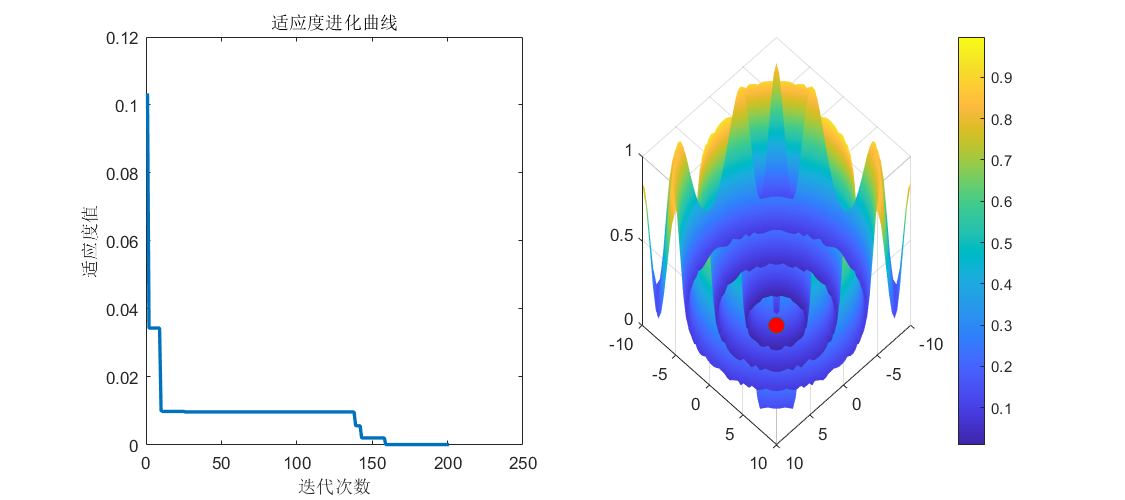

subplot(1, 2, 1)
plot(trace, 'LineWidth', 2);
xlabel('迭代次数');
ylabel('适应度值');
title('适应度进化曲线');
len = 50;
xRange = linspace(Xx, Xs, len);
yRange = linspace(Xx, Xs, len);
[xMap, yMap] = meshgrid(xRange, yRange);
zMap = zeros(len);
for i = 1 : len
    for j = 1 : len
        zMap(i, j) = ObjFun([xMap(i, j), yMap(i, j)]);
    end
end
subplot(1, 2, 2)
surf(xRange, yRange, zMap);
colorbar;
view(-45, -45);
shading interp
hold on
plot3(X(1), X(2), Y, 'o', 'MarkerFaceColor', 'r', 'MarkerSize', 10);
hold off
set(gcf, 'Position', [400, 200, 900, 400]);

function result = ObjFun(x)
x1 = x(1);
x2 = x(2);
t = x1^2 + x2^2;
result = 0.5 + (sin(sqrt(t))^2 - 0.5) / (1 + 0.001 * t)^2;
end